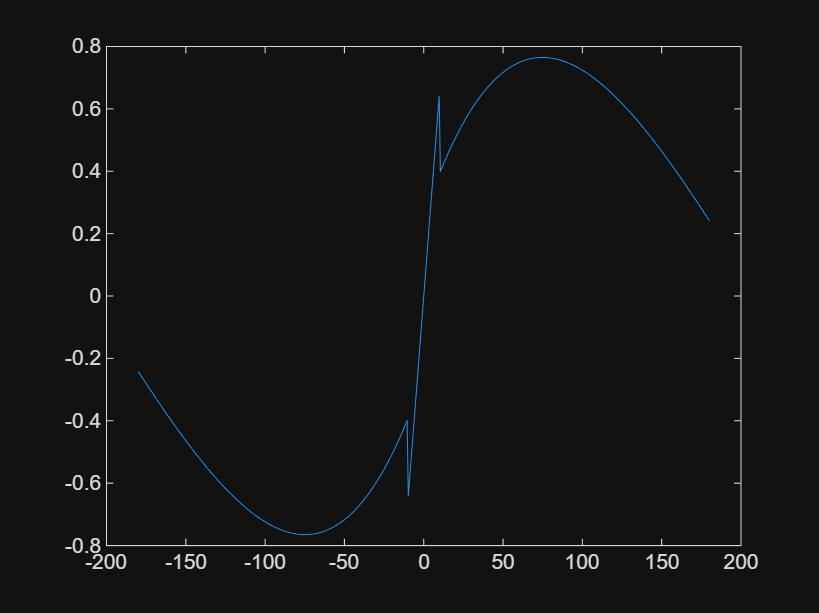


% constants

aspectRatio = 4;
skinDrag = 0.02;
flapAngle = 0;
liftSlope = 2*pi;
zeroLiftAoA = 0;
stallHigh = deg2rad(10);
stallLow = deg2rad(-10);

function friction = getFrictionAtNormal(flapAngle)
    friction = 1.98 - -4.26e-2 * flapAngle*flapAngle + 2.1e-1 * flapAngle;
end
function coeffs = getCoefficientsLowAoA( ...
    angleOfAttack, ...
    liftSlope, ...
    zeroLiftAoA, ...
    skinDrag, ...
    flapAngle, ...
    aspectRatio)
    
    liftCoefficient = liftSlope * (angleOfAttack - zeroLiftAoA);
    inducedAlpha = liftCoefficient / pi*aspectRatio;
    effectiveAlpha = angleOfAttack - zeroLiftAoA - inducedAlpha;

    tangentialCoefficient = skinDrag * cos(effectiveAlpha);
    normalCoefficient = (liftCoefficient + tangentialCoefficient*sin(effectiveAlpha)) / cos(effectiveAlpha);

    dragCoefficient = normalCoefficient*sin(effectiveAlpha) + tangentialCoefficient*cos(effectiveAlpha);

    momentCoefficient = -normalCoefficient * (0.25 - 0.175*(1 - 2*effectiveAlpha/pi));

    coeffs = [liftCoefficient, dragCoefficient, momentCoefficient];
end

function coeffs = getCoefficientsStall(angleOfAttack, ...
    liftSlope, ...
    zeroLiftAoA, ...
    stallHigh, ...
    stallLow, ...
    skinDrag, ...
    flapAngle, ...
    aspectRatio)
    
    % lerp incuded angle to 0 at +- 90deg

    if angleOfAttack > stallHigh
        lerpFactor = (pi/2 - angleOfAttack) / (pi/2 - stallHigh);
        liftPreStall = liftSlope * (stallHigh - zeroLiftAoA);
        inducedAlphaPreStall = liftPreStall / pi * aspectRatio;
    else
        lerpFactor = (-pi/2 - angleOfAttack) / (-pi/2 - stallLow);
        liftPreStall = liftSlope * (stallLow - zeroLiftAoA);
        inducedAlphaPreStall = liftPreStall / pi * aspectRatio;
    end
    inducedAlpha = inducedAlphaPreStall * (1 - lerpFactor);

    effectiveAlpha = angleOfAttack - zeroLiftAoA - inducedAlpha;

    Cd90 = getFrictionAtNormal(flapAngle); % friction at 90deg is dependent on flap angle
    
    normalCoefficient = Cd90 * sin(effectiveAlpha) * (1/(0.56 + 0.44*abs(sin(effectiveAlpha))) - 0.41*(1 - exp(-17/aspectRatio)));
    tangentCoefficient = 0.5 * skinDrag * cos(effectiveAlpha);

    liftCoefficient = normalCoefficient*cos(effectiveAlpha) - tangentCoefficient*sin(effectiveAlpha);
    dragCoefficient = normalCoefficient*sin(effectiveAlpha) + tangentCoefficient*cos(effectiveAlpha);
    momentCoefficient = -normalCoefficient * (0.25 - 0.175*(1 - 2*effectiveAlpha/pi));

    coeffs = [liftCoefficient, dragCoefficient, momentCoefficient];

end

function coeffs = getCoefficients( ...
    angleOfAttack, ...
    liftSlope, ...
    zeroLiftAoA, ...
    stallHigh, ...
    stallLow, ...
    skinDrag, ...
    flapAngle, ...
    aspectRatio)

    if angleOfAttack >= stallLow && angleOfAttack <= stallHigh
        coeffs = getCoefficientsLowAoA( ...
            angleOfAttack, ...
            liftSlope, ...
            zeroLiftAoA, ...
            skinDrag, ...
            flapAngle, ...
            aspectRatio);
    else
        % adjust blending region for different flap angles
        % this accounts for the harsher region changes with higher angles
        
        lerpFactorHigh = (rad2deg(flapAngle) + 50) / 100;
        lerpFactorLow = (-rad2deg(flapAngle) + 50) / 100;
        padAngleHigh = 0; %deg2rad(15)+ lerpFactorHigh * (15-5);
        padAngleLow = 0; %deg2rad(15) + lerpFactorLow * (15-5);
        paddedStallHigh = stallHigh + padAngleHigh;
        paddedStallLow = stallLow - padAngleLow;

        if angleOfAttack > paddedStallHigh || angleOfAttack < paddedStallLow
            % no blending required
            coeffs = getCoefficientsStall(angleOfAttack, liftSlope, zeroLiftAoA, stallHigh, stallLow, skinDrag, flapAngle, aspectRatio);
            return;
        else
            % blending between regions
            if angleOfAttack > stallHigh
                preStall = getCoefficientsLowAoA(stallHigh, liftSlope, zeroLiftAoA, skinDrag, flapAngle, aspectRatio);
                postStall = getCoefficientsStall(paddedStallHigh, liftSlope, zeroLiftAoA, stallHigh, stallLow, skinDrag, flapAngle, aspectRatio);
                lerpFactor = (angleOfAttack - stallHigh) / (paddedStallHigh - stallHigh);
            else
                preStall = getCoefficientsLowAoA(stallLow, liftSlope, zeroLiftAoA, skinDrag, flapAngle, aspectRatio);
                postStall = getCoefficientsStall(paddedStallLow, liftSlope, zeroLiftAoA, stallHigh, stallLow, skinDrag, flapAngle, aspectRatio);
                lerpFactor = (angleOfAttack - stallLow) / (paddedStallLow - stallLow);
            end
            coeffs = preStall + lerpFactor * (postStall - preStall);
        end
    end
end

correctedLiftSlope = liftSlope * (aspectRatio / (aspectRatio + 2*(aspectRatio+4)/(aspectRatio+2)));

l = 500;
alphas = linspace(-180, 180, l);
alphas_rad = deg2rad(alphas);
lifts = zeros(1, l);
drags = zeros(1, l);
moments = zeros(1, l);
for i = 1:l
    coeffs = getCoefficients( ...
        alphas_rad(i), ...
        correctedLiftSlope, ...
        zeroLiftAoA, ...
        stallHigh, ...
        stallLow, ...
        skinDrag, ...
        flapAngle, ...
        aspectRatio);
    lifts(i) = coeffs(1);
    drags(i) = coeffs(2);
    moments(i) = coeffs(3);
end

plot(alphas, lifts)